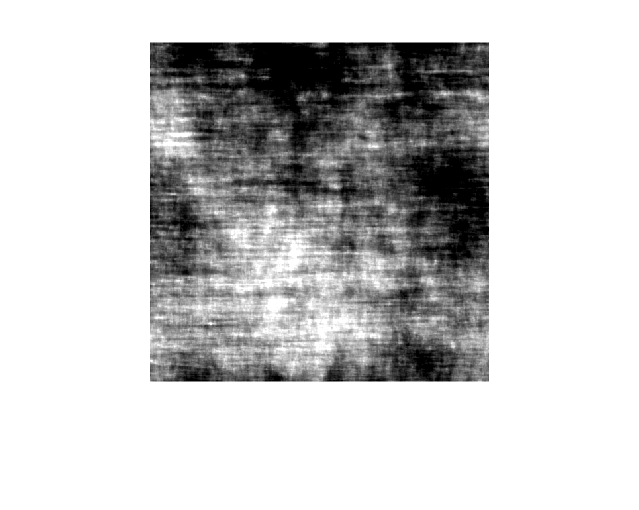

%EXERCICI1

u1 =im2double(imread('roma.png'));
u2 =im2double(imread('texture.png'));

%Tranformades de Fourier
fu1 = fft2(u1);
fu2 = fft2(u2);

%Moduls de les tranformades
mod_fu1 = abs(fu1);
mod_fu2 = abs(fu2);

%Fase de les transformades
phase_fu1 = angle(fu1);
phase_fu2 = angle(fu2);

%Noves imatges
fv1 = mod_fu1.*exp(1i*phase_fu2);
fv2 = mod_fu2.*exp(1i*phase_fu1);

v1 = ifft2(fv1);
v2 = ifft2(fv2);

imshow(v1);

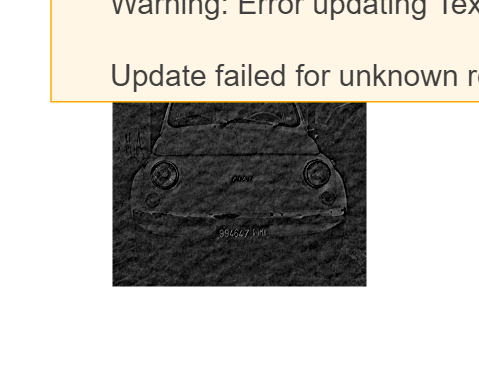

imshow(v2);

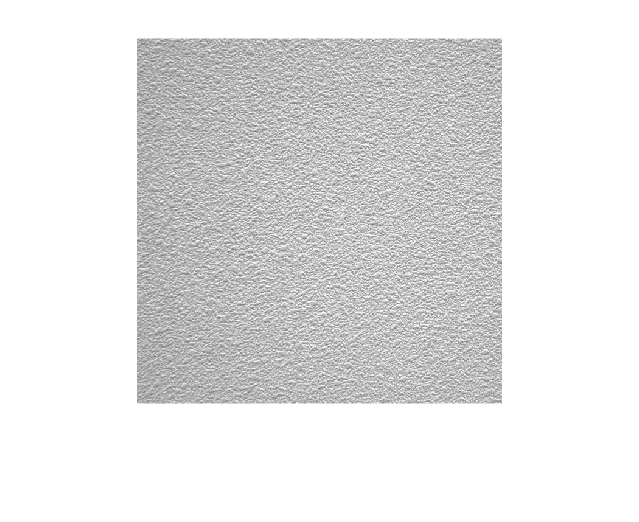


%EXERCICI2(RPN)

img1 =im2double(imread('textil-1-gray.png'));
img2 =im2double(imread('textil-2-gray.png'));

%Crear una imatge amb soroll aleatori gaussià
A = zeros(size(img1,1),size(img1,2));
noise = imnoise(A,'gaussian');
%agafar la fase de la transformada de fourier del soroll
f_noise = fft2(noise);
phase_noise = angle(f_noise);
%Fer servir la formula per crear la nova imatge
f_img1 = fft2(img1);
s_img1 = abs(f_img1).*exp(1i*phase_noise);
final_img1 = ifft2(s_img1);

%Fem el plot de la imatge original i la final
imshow(img1);

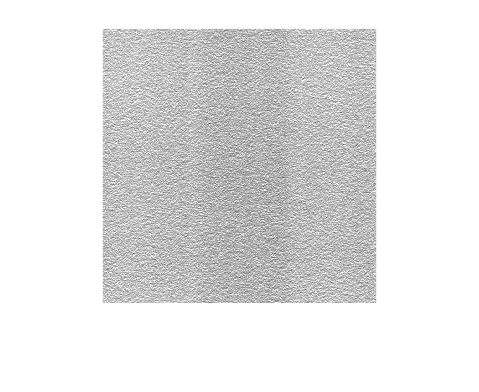

imshow(final_img1);

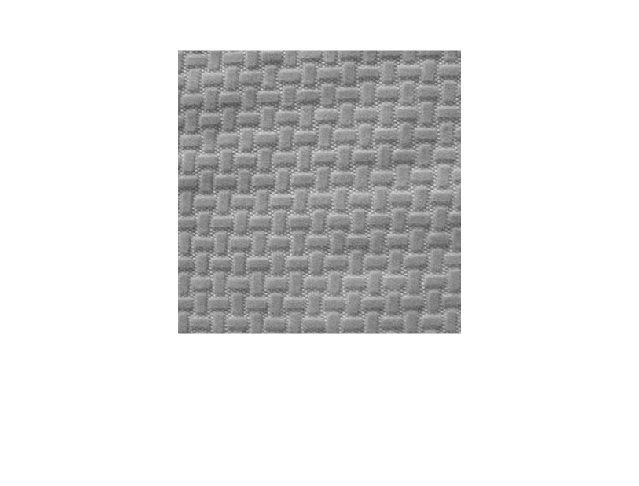


%Fem el mateix per la textura 2
B = zeros(size(img2,1),size(img2,2));
noise = imnoise(B,'gaussian');
f_noise = fft2(noise);
phase_noise = angle(f_noise);
f_img2 = fft2(img2);
s_img2 = abs(f_img2).*exp(1i*phase_noise);
final_img2 = ifft2(s_img2);

%Fem el plot de la imatge original i la final
imshow(img2);

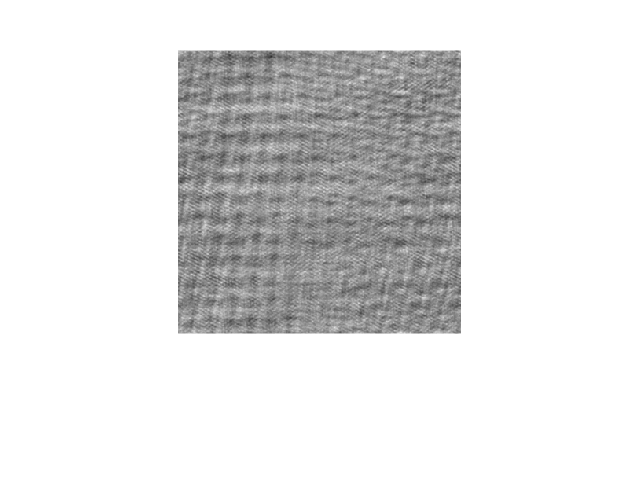

imshow(final_img2);

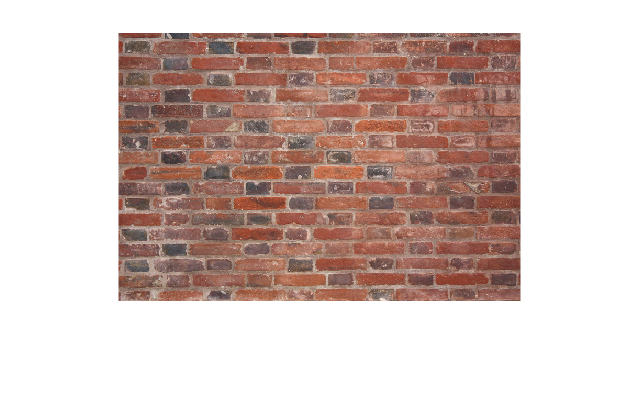



%Color

img = im2double(imread('bricks.png')); 

%separem els canals RGB
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

%Calculem la transformada de Fourier, la fase i la magnitud de cada canal
%RED
fourierR = fft2(R);
faseR = angle(fourierR);
modulR = abs(fourierR);

%GREEN
fourierG = fft2(G);
faseG = angle(fourierG);
modulG = abs(fourierG);

%BLUE
fourierB = fft2(B);
faseB = angle(fourierB);
modulB = abs(fourierB);

%Creem el soroll
C = zeros(size(img,1),size(img,2));
noise = imnoise(C,'gaussian');
f_noise = fft2(noise);
phase_noise = angle(f_noise);

%Apliquem la fòrmula per a tenir les imatges de fourier finals per a cada
%canal

final_fourierR = modulR.*exp(1i*(phase_noise + faseR));
final_fourierG = modulG.*exp(1i*(phase_noise + faseG));
final_fourierB = modulB.*exp(1i*(phase_noise + faseB));

%Unim les tres imatges i en fem la inversa per a tenir la textura
final_fourier = cat(3, final_fourierR, final_fourierG, final_fourierB);
img_final = ifft2(final_fourier);

imshow(img)

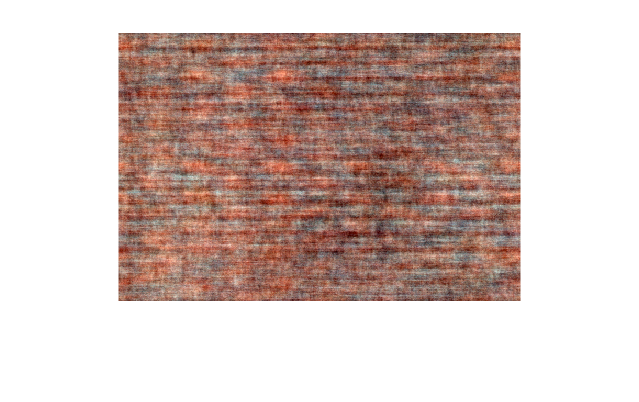

imshow(img_final);